**Load golf ball data**

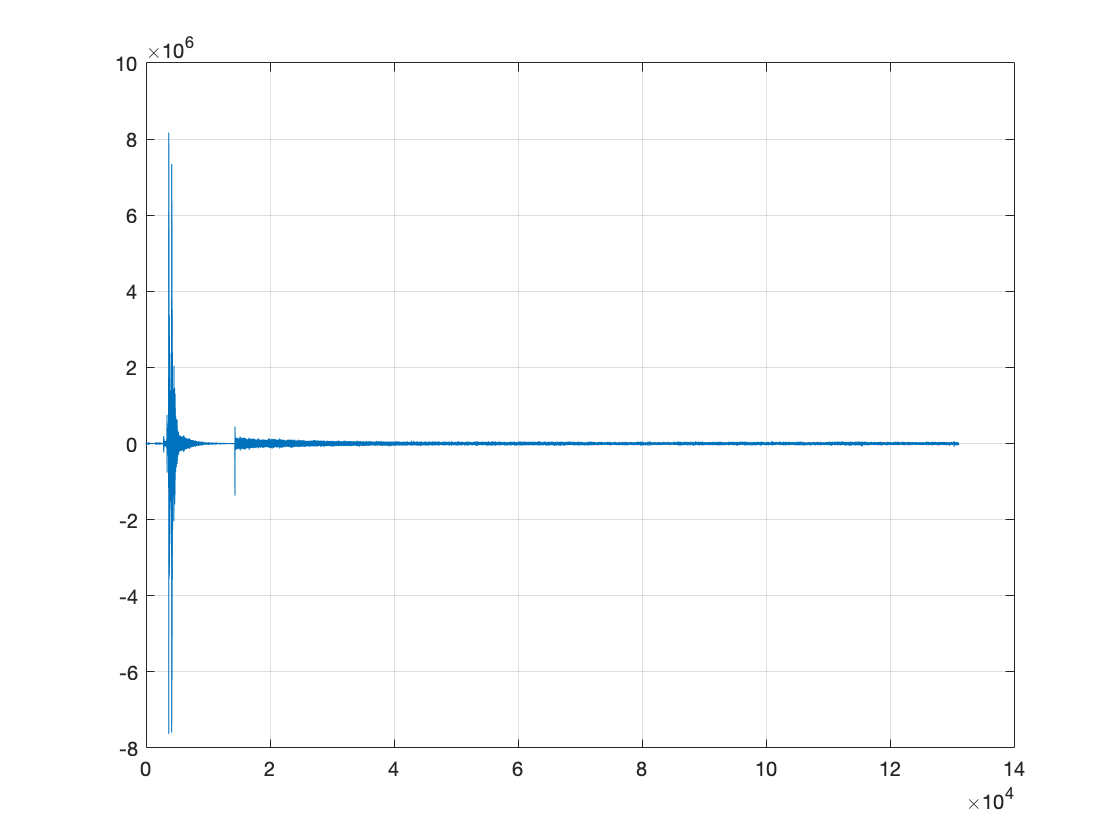

close all;
clear;

% Load golf shot data
filename = 'driver_shot.txt';
AllData = fileread(filename);
[~, beg_idx] = regexp(AllData,':'); % start extracting data after ':' character is found 
AllData = AllData(beg_idx+1:end);
AllData = textscan(AllData,'%s');
GolfBallData = str2double(AllData{1}); % Data values has all the data values from the .txt file 

figure; plot(GolfBallData); grid on; 

**Parameters:**

fs = 17045; %Sampling freq
nfft = 1024; %FFT length
L = 90; %Window length
overlap = floor(0.85*L); % 50% overlap
N = 0; % User-defined. Used for adaptive threshold later.
w1 = kaiser(L,0.1);


**Signal data:**

% SIGNAL
signal = GolfBallData;
signal = signal((floor(0.205*fs)+1):floor(0.32*fs));

**Calling Spectrogram function:**

%Spectrogram 
[Spec_t,freq,Spec_mag,Spec] = spectrogram_function(signal,w1,overlap,nfft,fs);
[f_bins,nframes] = size(Spec_mag); % Number of freq bins and frames

**Adaptive threshold**

hist_length = floor(length(freq)/8); % Length hist = 1/8 of num. bins
modal_intensity = zeros(1,nframes);

for i = 1:nframes
    
    frame = Spec_mag(:,i); %Current time frame
    
    [hist,edges] = histcounts(frame,hist_length); %Get histogram counts and edges
    hist_smooth = movmean(hist,5); % Smooth with 5-pt moving avg filter
    index_modal_intensity = find(hist_smooth == max(hist_smooth)); %Index for modal intensity
    index_modal_intensity = index_modal_intensity(1); %Choose first index if max is over multiple bins
    modal_intensity(i) = (edges(index_modal_intensity)+edges(index_modal_intensity+1))/2; %Find corresponding intensity
    smooth_modal_intensity = movmean(modal_intensity,5); %Smooth noise profile
    
    threshold = smooth_modal_intensity(i) + N*std(frame); %Set threshold for current time frame
    
    for j = 1:length(freq)
       if frame(j) < threshold %If element in frame is less than threshold then set to 0
           frame(j) = 0;
       end
    end
   
    Spec_mag(:,i) = frame;
end

**Setting a target threshold:**

% % FOR DISPLAY:
% 
% for i = 1:nframes
%     frame = Spec_mag(:,i);
%     for j = 1:length(freq)
%        if frame(j) < 78
%            frame(j) = 45;
%        end
%     end
%     Spec_mag(:,i)=frame;
% end

**Peak tracking**

freq_at_peaks = zeros(1,nframes);
time_at_peaks = Spec_t;
amplitude = zeros(1,nframes);

for i = 1:nframes
    frame = Spec_mag(:,i); %Current time frame
    
    if max(frame) > 78
        
        %For curve fitting / peak tracking:
        index = find(frame == max(frame)); % Index used to find freq. at peak
        freq_at_peaks(i) = freq(index); % frequency at peak
        
        for j = (index-7):(index+7)
            amplitude(i) = amplitude(i) + 10^(frame(j)/20);
        end

    else
        time_at_peaks(i) = 0;
        
    end
end
freq_at_peaks = freq_at_peaks(freq_at_peaks ~= 0);
time_at_peaks = time_at_peaks(time_at_peaks ~= 0);
amplitude = amplitude(amplitude ~= 0);

**Plotting Spectrogram:**

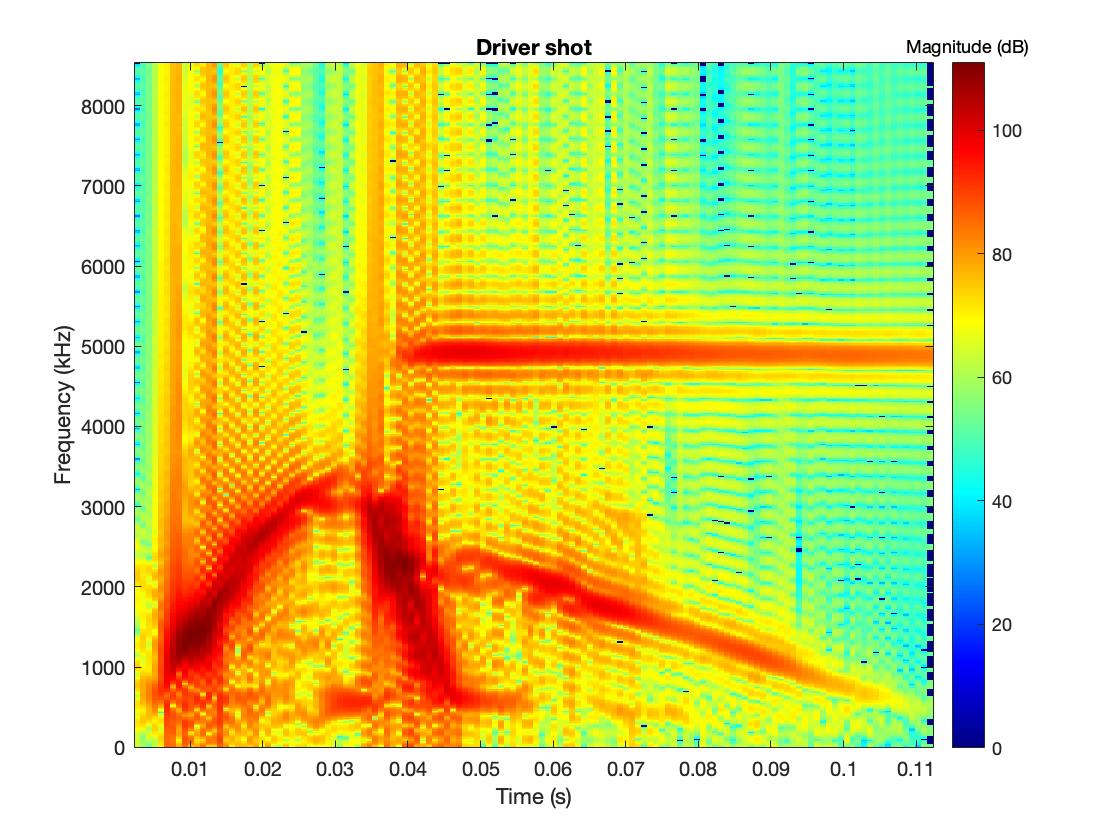

%Plotting Spectrogram

imagesc(Spec_t,freq,Spec_mag);
set(gca,'YDir','normal') % Flip y-axis such that 0 kHz is at the bottom
h = colorbar; % Create colour bar showing magnitude
colormap('jet')
set(get(h,'title'),'string','Magnitude (dB)'); % Label colourbar
title("Driver shot"), xlabel("Time (s)"),ylabel("Frequency (kHz)")

**Plot at peaks:**

% freq_at_peaks = freq_at_peaks(2:34);
time_at_peaks = time_at_peaks(2:33);
amplitude = amplitude(2:33);

time_at_peaks = time_at_peaks - time_at_peaks(1);
[fit, gof] = club_driver_amp_fit(time_at_peaks, amplitude)

fit =      Linear model Poly6:
     fit(x) = p1*x^6 + p2*x^5 + p3*x^4 + p4*x^3 + p5*x^2 + 
                    p6*x + p7
     Coefficients (with 95% confidence bounds):
       p1 =   3.676e+18  (1.941e+18, 5.41e+18)
       p2 =  -2.906e+17  (-4.236e+17, -1.576e+17)
       p3 =   8.558e+15  (4.679e+15, 1.244e+16)
       p4 =  -1.125e+14  (-1.66e+14, -5.887e+13)
       p5 =    5.78e+11  (2.249e+11, 9.31e+11)
       p6 =  -2.359e+08  (-1.208e+09, 7.359e+08)
       p7 =    1.94e+05  (-6.318e+05, 1.02e+06)

gof = struct with fields:
           sse: 5.0777e+12
       rsquare: 0.9149
           dfe: 25
    adjrsquare: 0.8945
          rmse: 4.5067e+05


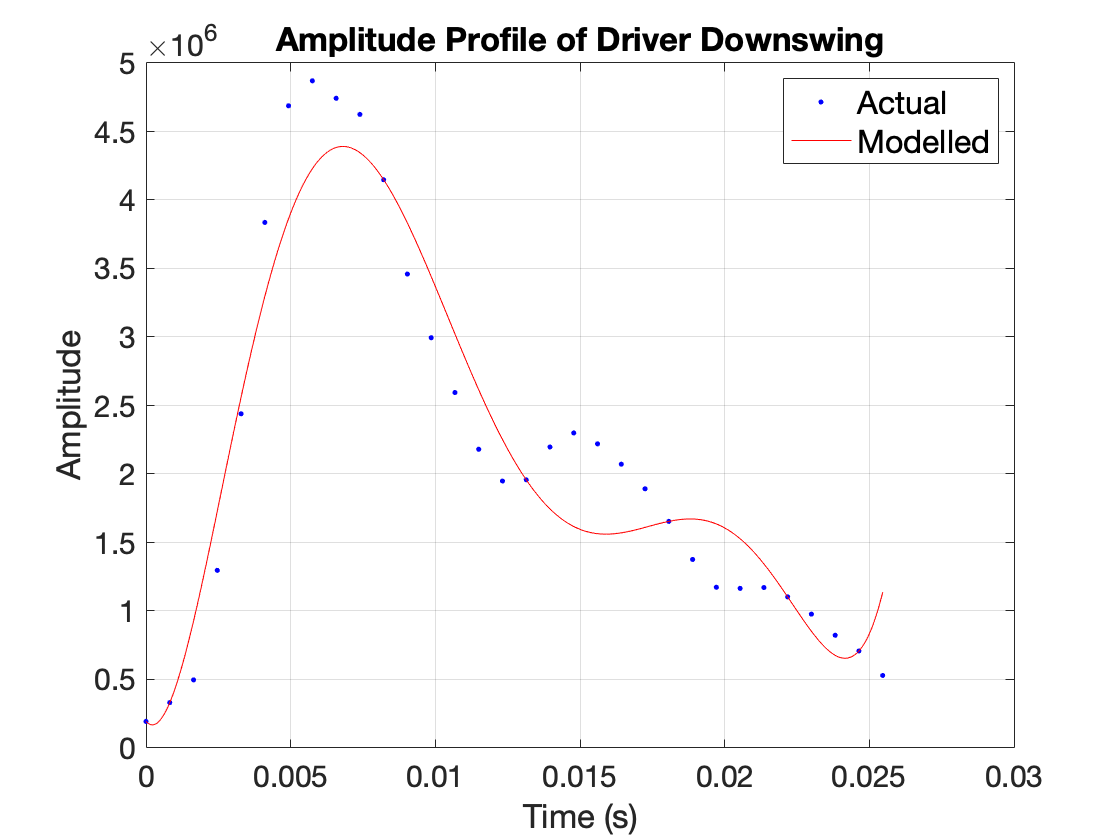

set(gca,'FontSize',15);

**Calculating mean error:**

%Driver club amp
model_at_peaks = feval(fit,time_at_peaks);
model_at_peaks = model_at_peaks.';
err = abs(model_at_peaks-amplitude);
mean_err = mean(err)

mean_err = 3.2369e+05